## Simulazione

clc
clear
alpha = pi/2;
[coeffs_num,coeffs_den] = fdt_vab_lineare(alpha);

$$G = \frac{19550.0}{1.0e+5\,s^{2}+1.624e+6}$$

$$num = 195.5$$

$$den = 1000.0\,s^{2}+16240.0$$

fdt_vab_non_lineare();

$$theta2\_ris = \begin{array}{l} -\frac{\left(8.484e+8\,\sin\left(2.0\,q_{2}\right)-9.442e+9\,\cos\left(2.0\,q_{2}\right)-7.151e+11\,C_{m}-1.046e+12\,\cos\left(\mathrm{alpa}+2.0\,q_{2}-0.7406\right)+1.25e+7\,\sin\left(\mathrm{alpa}\right)-2.888e+13\,\sin\left(\sigma_{2}\right)+75210.0\,{q_{2,p}}^{2}\,\cos\left(\sigma_{3}\right)-1.377e+11\,{q_{2,p}}^{2}\,\cos\left(q_{2}\right)+68760.0\,{q_{2,p}}^{2}\,\sin\left(\sigma_{3}\right)-1.259e+11\,{q_{2,p}}^{2}\,\sin\left(q_{2}\right)+80960.0\,{q_{2,p}}^{2}\,\cos\left(\mathrm{alpa}-q_{2}\right)+5623.0\,C_{m}\,\sin\left(2.0\,q_{2}\right)+5.624e+6\,{q_{2,p}}^{2}\,\sin\left(3.0\,\mathrm{alpa}-1.0\,q_{2}\right)+9.0e+10\,C_{m}\,\cos\left(\mathrm{alpa}+q_{2}\right)-75210.0\,{q_{2,p}}^{2}\,\cos\left(2.0\,\mathrm{alpa}+q_{2}\right)+68760.0\,{q_{2,p}}^{2}\,\sin\left(2.0\,\mathrm{alpa}+q_{2}\right)+3.906e+5\,C_{m}\,\sigma_{1}-3.906e+5\,C_{m}\,\cos\left(\sigma_{2}\right)+1.1e+9\,C_{m}\,\cos\left(q_{2}\right)-1.203e+9\,C_{m}\,\sin\left(q_{2}\right)-1.03e+13\,{q_{2,p}}^{2}\,\sin\left(\mathrm{alpa}+q_{2}\right)+2.5e+5\right)\,1.0}{2.348e+10\,\cos\left(\mathrm{alpa}-0.8302\right)-28710.0\,\sin\left(2.0\,q_{2}\right)-2.127e+8\,\cos\left(2.0\,q_{2}-1.481\right)+2.348e+10\,\cos\left(\mathrm{alpa}+2.0\,q_{2}+0.8302\right)-6.995e+6\,\sigma_{1}+6.479e+11\,\cos\left(\sigma_{2}\right)+4.3e+12}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2.0\,\mathrm{alpa}-2.0\,q_{2}\right)\\ \sigma_{2}=2.0\,\mathrm{alpa}+2.0\,q_{2}\\ \sigma_{3}=2.0\,\mathrm{alpa}-1.0\,q_{2} \end{array}$$

funzione creata


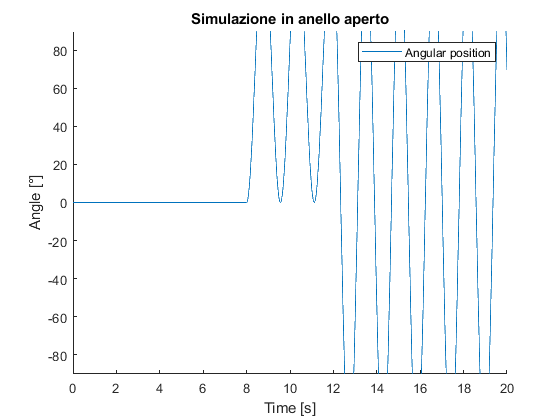


t_end = 20;
Ts = 1/100;
control_on = 0;
k_p = -1;
try
      sim  VABSim.slx 
catch err
      err
      err.stack
      line = err.stack(1).line
end

clearvars no_control_sim;
no_control_sim(1,:) = sim_res_linear;

figure
hold on
plot(tout, no_control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')
ylim([-90 90])
legend('Angular position')
title('Simulazione in anello aperto')

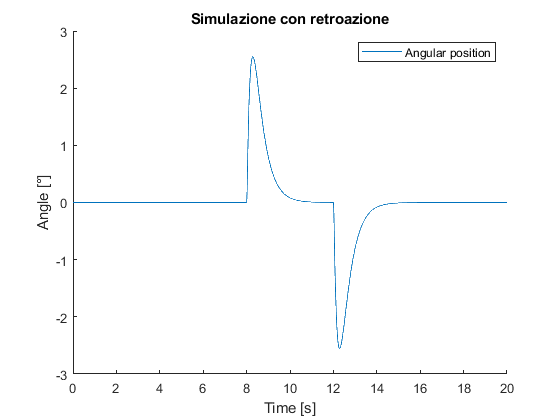

control_on = 1;
k_p = 10;

try
      sim  VABSim.slx 
catch err
      err
      err.stack
      line = err.stack(1).line
end
clearvars control_sim;
control_sim(1,:) = sim_res_linear;

figure
hold on
plot(tout, control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')
legend('Angular position')
title('Simulazione con retroazione')

Unrecognized function or variable 'sim_res_non_linear'.